% Section 1: Loading
load bach_fugue.mat


bpm = 120;

fs = 11025;

qtr_per_second = bpm/60;
seconds_per_qtr = 1/qtr_per_second;
seconds_per_pulse = seconds_per_qtr/4;

dur_each_note1 = theVoices(1).durations * seconds_per_pulse;
dur_each_note2 = theVoices(2).durations * seconds_per_pulse;
dur_each_note3 = theVoices(2).durations * seconds_per_pulse;

x1_len = ceil(sum(dur_each_note1)+1)*fs;
x2_len = ceil(sum(dur_each_note2)+1)*fs;
x3_len = ceil(sum(dur_each_note3)+1)*fs;

xx_len = 0;
if (x1_len > x2_len)
    xx_len = x1_len;
end
if (x3_len > xx_len)
    xx_len = x3_len;
end

n1 = ceil(theVoices(1).startPulses(end)*seconds_per_pulse*fs);
durae = dur_each_note1(end);
xx_len = ceil(n1 + durae*fs);
%xx_len = ceil(sum(max)+1)*fs; %xx_len we got da total length of melody in s, then multiple to how many samples needed each sec
xx = zeros(1, xx_len); %the length of 
x = 1*exp(j*0);

for jj = 1:length(theVoices)
    dur_each_note = theVoices(jj).durations * seconds_per_pulse;
    x1_len = ceil(sum(dur_each_note)+1)*fs;
    x1 = zeros(1, xx_len);
    n1 = theVoices(jj).startPulses(1)*seconds_per_pulse*fs;
    for kk = 1:length(theVoices(jj).noteNumbers)
        keynum = theVoices(jj).noteNumbers(kk);
        durae = dur_each_note(kk);
        note = key2note(x, keynum, durae);
    
        %creating the Envelope
        Env_length = length(note);
    
        Action = round(0.1*Env_length);
        Drop = round(0.1*Env_length);
        Sustain = round(0.6*Env_length);
        Release = Env_length - Action - Drop - Sustain;
    
        Env_Action = linspace(0,1, Action);
        Env_Drop = linspace (1,0.8, Drop);
        Env_Sustain = linspace (0.8, 0.6, Sustain);
        Env_Release = linspace (0.6,0, Release);
    
        Env = [Env_Action Env_Drop Env_Sustain Env_Release];
        Env = Env(1:length(note));
    
        note = Env.*note;
    
        n2 = n1 - 1 + length(note);
        x1(n1:n2) = x1(n1:n2) + note; %<=== Insert the note
        n1 = theVoices(jj).startPulses(kk)*seconds_per_pulse*fs;
    end

    for ii = 1:length(x1)
    xx(ii) = xx(ii) + x1(ii);
    end
end

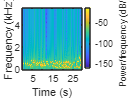

spectrogram(xx,1024,[],512,fs,'yaxis')

soundsc(xx);